## 频分多址实验

#### 参数设置

% 载波正交 BPSK
clearvars;
close all;
clc;
rng(2023);  %固定随机种子，保证结果可复现

% 脉冲成形波形参数
T = 0.01; % 周期
V = 1/sqrt(T); % 幅度

% 用户数（>=2）
N_u = 4;

% 载波参数
delta_fc = 200; % 载波频率间隔
f_lc = 200; % 最低载波频率
f_c = f_lc + (0:N_u-1)*delta_fc; % 载波频率，满足f_c(n)*T为整数


% 最小时间间隔
delta_t = 1e-4;

% 每个符号周期采样次数
num_t = round(T/delta_t);%round是四舍五入

% 功率谱计算选项：1为计算，0为不计算
if_ps = 1;

N_s = 1e5; % 符号个数
N_b = N_s; % 每用户信息比特数

Es = V^2*T; % 符号能量
Eb = Es; % BPSK的比特能量

% 仿真时间
t = (delta_t:delta_t:N_s*T);%刚好支持发送所有符号，点数为Ns*100

% 功率谱滑动窗参数
win_size = 100; % 滑动窗长与符号周期的比值 
win_step = 80; % 滑动窗移动步长与符号周期的比值
win_num = floor((N_s-win_size)/win_step)+1; % 滑动窗个数

% 功率谱频率分辨率
delta_f = 1/T/win_size;

% 功率谱采样频点
f = (0:win_size*num_t-1) * delta_f; % FFT所得功率谱循环周期为1/delta_t

#### 传输过程(改变噪声功率谱密度)

% 噪声的单边功率谱密度
a=[0.1:0.1:2];
b=[2:2:20];
n0_all = [a,b];
ber_theory_all=zeros(1,length(n0_all));
ber_real_all=zeros(1,length(n0_all));

for anyma=1:length(n0_all)
n0=n0_all(anyma);
    
% 成形脉冲
p_t = V * ones(num_t, 1);

% 基带脉冲成形
x0_t = zeros(N_u, N_s*num_t);

% 发送波形
x_t = zeros(1, N_s*num_t);

tic;

% 随机生成符号序列
bit_data = randi([0 1], N_u, N_b);

% 转化为BPSK调制后的电平序列（mod_data）
mod_data = ma_gray_map_real_M2(bit_data);

% 脉冲成形
for n_u = 1:N_u
    for n_s = 1:N_s
        x0_t(n_u,num_t*(n_s-1)+1:num_t*n_s) = mod_data(n_u,n_s)*p_t;
        %服了操你妈的还真的可以这样赋值，只要维数相同
    end
end
% 逐用户上变频
for n_u = 1:N_u
    x_t = x_t + x0_t(n_u,:)*sqrt(2).*cos(2*pi*f_c(n_u)*t);
end

%计算功率谱，储存在S_X中
if if_ps == 1
    S_X = zeros(1,win_size*num_t); % 功率谱初始化
    for win_id = 1:win_num % 滑动窗编号
        % 滑动窗的时间范围
        window = (win_id-1)*win_step*num_t+1:(win_id-1)*win_step*num_t+win_size*num_t;
        % 累加各窗内波形FFT的模方
        S_X = S_X + abs(fft(x_t(window))).^2;
    end
    S_X = S_X / win_num; % 窗之间求平均
    S_X = S_X / (num_t*win_size)^2 / delta_f; % 功率谱密度函数系数
end


% 加性噪声
noise_power = n0/2/delta_t;
noise = sqrt(noise_power) * randn(size(t));

% AWGN信道
y_t = x_t + noise;


% 等效基带接收波形
y0_t = zeros(N_u, N_s*num_t);

% 逐用户下变频
for n_u = 1:N_u
    y0_t(n_u,:) = y_t .* cos(2*pi*f_c(n_u)*t) ;
end

% 初始化接收符号
y = zeros(N_u, N_s);

% 逐用户最佳接收
for n_u = 1:N_u
    for n_s = 1:N_s 
        y(n_u,n_s) = y(n_u,n_s) + sum(y0_t(n_u,num_t*(n_s-1)+1:num_t*n_s))*delta_t;%对一段T时间序列积分就可以获得值
    end
end

% 最佳判决结果
bit_hat = ma_inverse_gray_map_real_M2(y);

% 差错比特
bit_err = xor(bit_data, bit_hat);
% 计算各用户的误比特率
ber = sum(bit_err,2);
ber = ber/N_b;
ber_av=sum(ber)/4;

ber_theory=qfunc(sqrt(Eb/(n0/2)));

toc;

ber_theory_all(anyma)=ber_theory;
ber_real_all(anyma)=ber_av;

end

历时 2.267316 秒。
历时 2.396903 秒。
历时 2.459826 秒。
历时 2.578545 秒。
历时 3.002588 秒。
历时 2.902244 秒。
历时 2.758002 秒。
历时 2.524938 秒。
历时 3.203285 秒。
历时 2.771343 秒。
历时 2.663866 秒。
历时 2.610408 秒。
历时 2.572730 秒。
历时 2.835012 秒。
历时 2.739639 秒。
历时 2.809342 秒。
历时 2.855816 秒。
历时 2.874290 秒。
历时 2.635974 秒。
历时 2.624888 秒。
历时 2.573405 秒。
历时 2.708528 秒。
历时 2.610017 秒。
历时 2.622406 秒。
历时 2.663485 秒。
历时 2.549805 秒。
历时 2.412565 秒。
历时 2.470483 秒。
历时 2.449044 秒。
历时 2.415051 秒。


#### 绘图

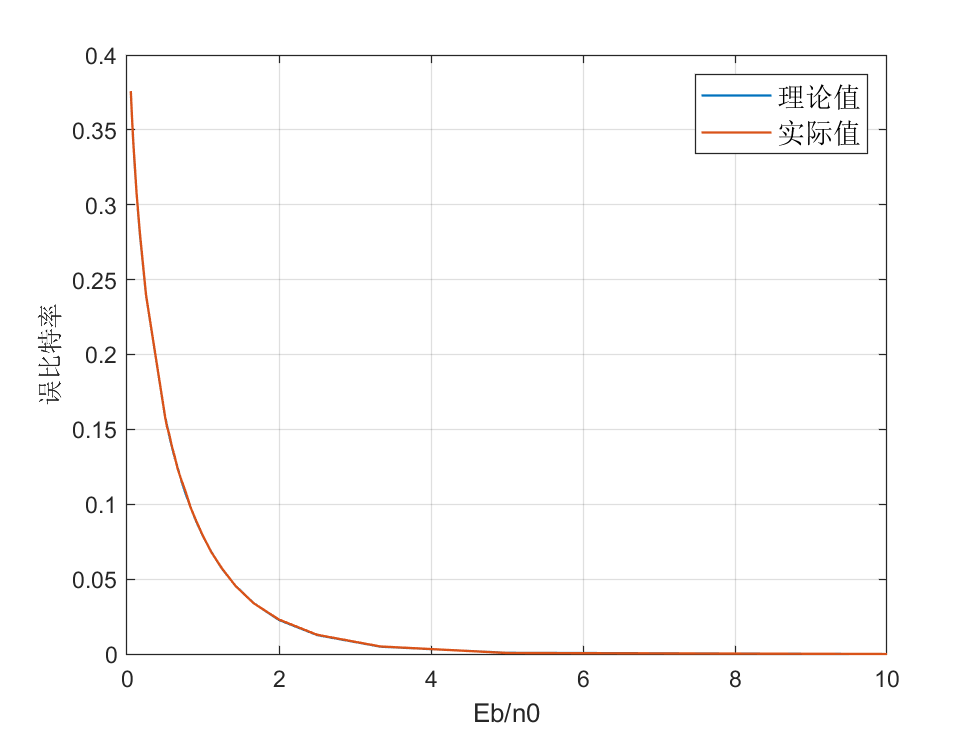

% 绘图
figure;
plot(Eb./n0_all, ber_theory_all, ...
        'LineWidth', 1);
hold on;
plot(Eb./n0_all, ber_real_all, ...
        'LineWidth', 1);
% hold on;
% plot((+delta_t:delta_t:4*T)', noise(1:4*num_t), ...
%         'LineWidth', 1);
xlabel('Eb/n0');
ylabel('误比特率');
%title('波形图');
box on;
grid on;
%legend('接收波形信号','发送波形信号','加性噪声信号','fontsize',12);
legend('理论值','实际值','fontsize',12);


% % 绘图
% figure;
% plot((delta_t:delta_t:4*T)', y_t(1:4*num_t), ...
%         'LineWidth', 1);
% hold on;
% plot((+delta_t:delta_t:4*T)', x_t(1:4*num_t), ...
%         'LineWidth', 1);
% % hold on;
% % plot((+delta_t:delta_t:4*T)', noise(1:4*num_t), ...
% %         'LineWidth', 1);
% xlabel('时间/s');
% ylabel('幅度/V');
% title('波形图');
% box on;
% grid on;
% %legend('接收波形信号','发送波形信号','加性噪声信号','fontsize',12);
% legend('接收波形信号','发送波形信号','fontsize',12);
% 
% if if_ps == 1
%     figure;
%     plot(f(f<1/2/delta_t), 10*log10(S_X(f<1/2/delta_t)), 'b', 'LineWidth', 1);
%     hold on;
%     % FFT所得功率谱循环周期为1/delta_t，将高频部分循环位移至负频率
%     plot(f(f>=1/2/delta_t)-1/delta_t, 10*log10(S_X(f>=1/2/delta_t)), 'b', 'LineWidth', 1);
%     xlabel('频率/Hz');
%     ylabel('功率谱密度/[dBW/Hz]');
%     title('x(t)功率谱');
%     xlim([-1/2/delta_t 1/2/delta_t])
%     ylim(10*log10(max(S_X)*[1E-5 1.2]));
%     box on;
%     grid on;
% end
% 
% 
% %对y_t求功率谱看看
% if if_ps == 1
%     S_Y = zeros(1,win_size*num_t); % 功率谱初始化
%     for win_id = 1:win_num % 滑动窗编号
%         % 滑动窗的时间范围
%         window = (win_id-1)*win_step*num_t+1:(win_id-1)*win_step*num_t+win_size*num_t;
%         % 累加各窗内波形FFT的模方
%         S_Y = S_Y + abs(fft(y_t(window))).^2;
%     end
%     S_Y = S_Y / win_num; % 窗之间求平均
%     S_Y = S_Y / (num_t*win_size)^2 / delta_f; % 功率谱密度函数系数
% end
% if if_ps == 1
%     figure;
%     plot(f(f<1/2/delta_t), 10*log10(S_Y(f<1/2/delta_t)), 'b', 'LineWidth', 1);
%     hold on;
%     % FFT所得功率谱循环周期为1/delta_t，将高频部分循环位移至负频率
%     plot(f(f>=1/2/delta_t)-1/delta_t, 10*log10(S_Y(f>=1/2/delta_t)), 'b', 'LineWidth', 1);
%     xlabel('频率/Hz');
%     ylabel('功率谱密度/[dBW/Hz]');
%     title('y(t)功率谱');
%     xlim([-1/2/delta_t 1/2/delta_t])
%     ylim(10*log10(max(S_Y)*[1E-5 1.2]));
%     box on;
%     grid on;
%     
% xlim([-5000 5000])
% ylim([-10 -0.5])
% end

### 函数

% M=2，由bit序列映射到电平符号

function mod_data = ma_gray_map_real_M2(bit_data)
% 对应的符号序列长度
[N_u, N_s] = size(bit_data);
mod_data = zeros(N_u, N_s);
% 逐用户、逐符号判断映射关系
for n_u = 1:N_u
    for n_s = 1:N_s
        current_bits = bit_data(n_u,n_s);
        if current_bits == 0
            mod_data(n_u,n_s) = -1;
        elseif current_bits == 1
            mod_data(n_u,n_s) = 1;
        end
    end
end
end

% M=2，由电平符号映射到bit序列
function demod_bit_data = ma_inverse_gray_map_real_M2(rx_data)
% 符号序列长度
[N_u, N_s] = size(rx_data);
demod_bit_data = zeros(N_u,N_s);
% 逐用户、逐符号判决
for n_u = 1:N_u
    for n_s = 1:N_s
        current_level = rx_data(n_u,n_s);
        if current_level < 0
            demod_bit_data(n_u,n_s) = 0;
        else
            demod_bit_data(n_u,n_s) = 1;
        end
    end
end
end
